clear all
cd /media/DataMOBsRAIDN/ProjectEmbReact/Mouse508/20170203/ProjectEmbReact_M508_20170203_EPM
% HPC
load('LFPData/LFP47.mat')
load('InstFreqAndPhase_H.mat')
load('H_Low_Spectrum.mat')


Look at the raw signal

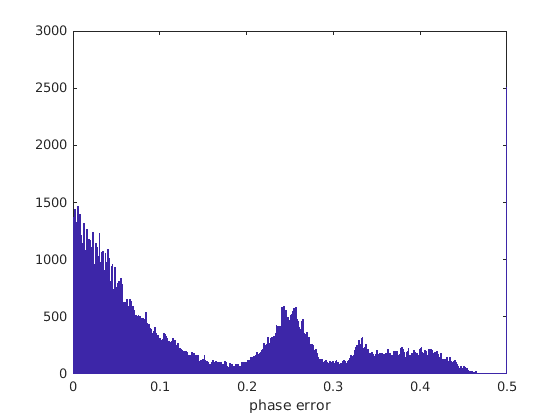


WV=mod(Data(LocalPhase.WV)-pi/2,2*pi)-pi;
PT=mod(Data(LocalPhase.PT)-pi/2,2*pi)-pi;
tps=Range(LocalPhase.PT);
Err=sqrt(diff(unwrap(WV)-unwrap(PT)).^2)./(sqrt(diff(unwrap(WV)).^2)+sqrt(diff(unwrap(PT)).^2))/2;
Errtsd=tsd(tps(2:end),Err);
ErrorEpoch=thresholdIntervals(Errtsd,0.2);
ErrorEpoch=dropShortIntervals(ErrorEpoch,0.05*1e4);
TotalEpoch=intervalSet(0,max(Range(LFP)));

figure
hist(Data(Errtsd),500)
xlabel('phase error')

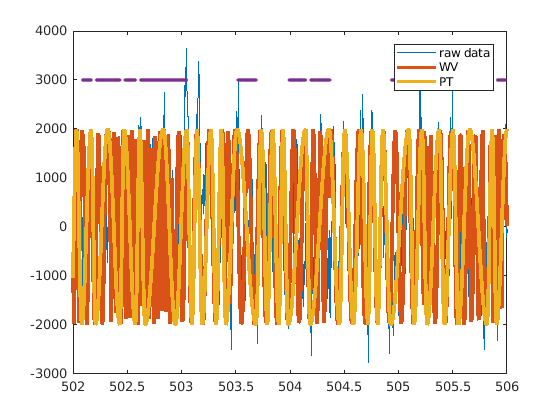


figure
plot(Range(LFP,'s'),Data(LFP))
hold on
plot(Range(LocalPhase.WV,'s'),sin(mod(Data(LocalPhase.WV)-pi/2,2*pi)-pi)*2000,'linewidth',3)
plot(Range(LocalPhase.WV,'s'),sin(mod(Data(LocalPhase.PT)-pi/2,2*pi)-pi)*2000,'linewidth',3)
plot(Range(Restrict(Errtsd,ErrorEpoch),'s'),Data(Restrict(Errtsd,ErrorEpoch))*0+3000,'.')
xlim([0 4]+502)
legend('raw data','WV','PT')

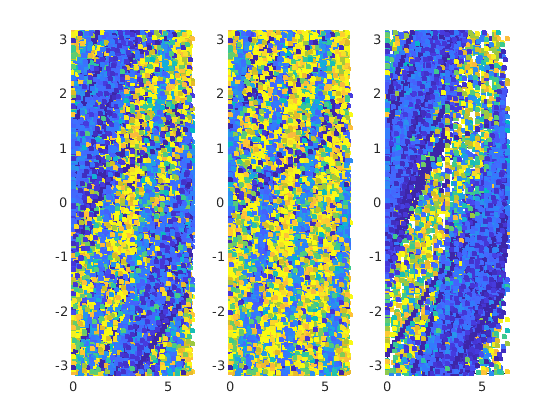


figure
subplot(131)
LocalPhase.WV=Restrict(LocalPhase.WV,ts(Range(LocalPhase.PT)));
scatter(Data(LocalPhase.PT),Data(LocalPhase.WV),20,(Data(LocalFreq.WV)),'filled')
xlim([0 2*pi]),ylim([-pi pi])
subplot(132)
scatter(Data(Restrict(LocalPhase.PT,ts(Range(Restrict(LocalPhase.WV,ErrorEpoch))))),Data(Restrict(LocalPhase.WV,ErrorEpoch)),20,(Data(Restrict(LocalFreq.WV,ErrorEpoch))),'filled')
xlim([0 2*pi]),ylim([-pi pi])
subplot(133)
epoc=TotalEpoch-ErrorEpoch;
scatter(Data(Restrict(LocalPhase.PT,ts(Range(Restrict(LocalPhase.WV,epoc))))),Data(Restrict(LocalPhase.WV,epoc)),20,(Data(Restrict(LocalFreq.WV,epoc))),'filled')
xlim([0 2*pi]),ylim([-pi pi])

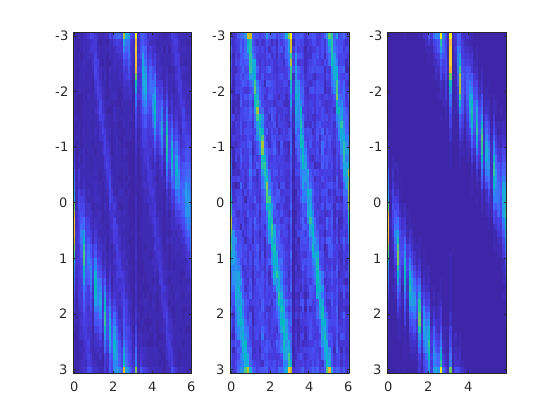


figure
subplot(131)
LocalPhase.WV=Restrict(LocalPhase.WV,ts(Range(LocalPhase.PT)));
hist2(Data(Restrict(LocalPhase.PT,ts(Range((LocalPhase.WV))))),Data((LocalPhase.WV)),50,50)
subplot(132)
hist2(Data(Restrict(LocalPhase.PT,ts(Range(Restrict(LocalPhase.WV,ErrorEpoch))))),Data(Restrict(LocalPhase.WV,ErrorEpoch)),50,50)
subplot(133)
epoc=TotalEpoch-ErrorEpoch;
hist2(Data(Restrict(LocalPhase.PT,ts(Range(Restrict(LocalPhase.WV,epoc))))),Data(Restrict(LocalPhase.WV,epoc)),50,50)

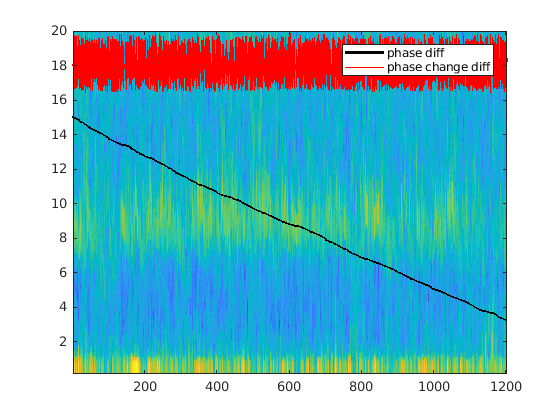

figure
imagesc(Spectro{2},Spectro{3},log(Spectro{1}')), axis xy
hold on
plot(tps/1e4,(unwrap(PT)-unwrap(WV))/3000+15,'linewidth',2,'color','k')
plot(tps(1:end-1)/1e4,diff(unwrap(PT)-unwrap(WV))/2+18,'r')
legend('phase diff','phase change diff')

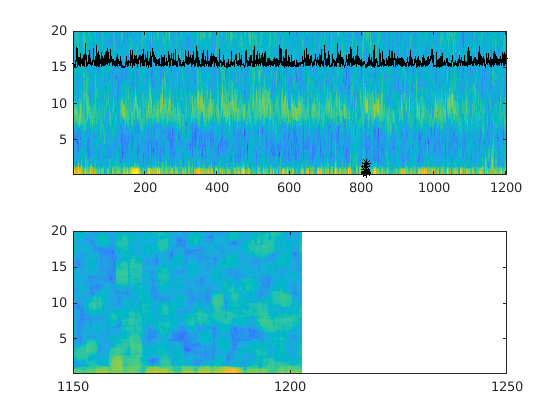


dat=Data(LocalPhase.WV);
tps=Range(LocalPhase.WV);
UnWrapped=unwrap(dat);
clear ErrBef ErrAft NewTps
num=1;
PerDur=100;
for k=1:PerDur:size(dat,1)-(2*PerDur+1)
    olddata=UnWrapped(k:k+PerDur-1);
    newdata=UnWrapped(k+PerDur:k+2*PerDur-1);
    c=polyfit(1:PerDur,olddata',1);
    newdataguess=[PerDur+1:PerDur*2]'*c(1)+c(2);
    olddataguess=[1:PerDur]'*c(1)+c(2);
    ErrBef(num)=nanmean(sqrt((olddataguess-olddata).^2));%./nanmean(abs(olddata));
    ErrAft(num,:)=(sqrt((newdataguess-newdata).^2));%./nanmean(abs(newdata));
    NewTps(num)=tps(k+PerDur);
    num=num+1;
end
ErrAfttsd=tsd(NewTps,mean(ErrAft')');
epoch=thresholdIntervals(ErrAfttsd,2,'Direction','Below');
epoch=mergeCloseIntervals(epoch,0.5*1e4);
epoch=dropShortIntervals(epoch,3*1e4);
figure
subplot(211)
imagesc(Spectro{2},Spectro{3},log(Spectro{1}')), axis xy
hold on
plot(Range(Restrict(ErrAfttsd,epoch),'s'),Data(Restrict(ErrAfttsd,epoch)),'k*')
plot(Range((ErrAfttsd),'s'),Data((ErrAfttsd))/15+15,'k')
subplot(212)
imagesc(Spectro{2},Spectro{3},log(Spectro{1}')), axis xy
hold on
plot(Range(Restrict(ErrAfttsd,epoch),'s'),Data(Restrict(ErrAfttsd,epoch)),'k*')
xlim([1150 1250])

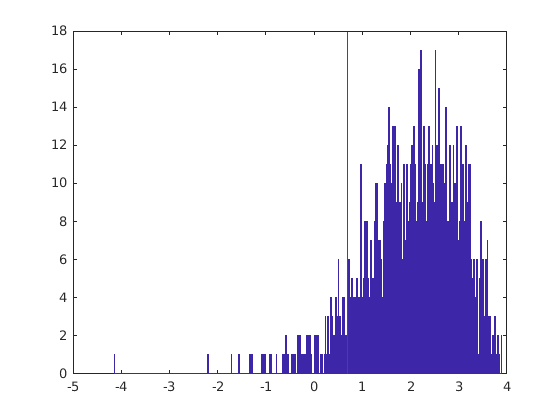


figure
hist(log(Data(ErrAfttsd)),500)
line(log(2)*[1 1],ylim,'color','r')